clear all, close all, clc

############### ############### ############### ############### 

## Prob-8.3.1

Given,

$P_A^T =\left\lbrack P\left(A_1 \right)\;P\left(A_2 \right)\right\rbrack$; Here, $A_1 \equiv \;$Early Containment Failure; $A_2 \equiv \;$Late Containment Failure. 

$P{\left(A_i \right)}=\sum_{j,1}^{n_D } P{\left(A_i |D_j \right)}\;P\left(D_j \right)$     $P\left(D_j \right)=$ probability of plant damage

Now, the Plant Damage State frequency Vector


$$P_D^T ={\left[P{\left(SBO\right)}\ \;P{\left(ATWS\right)}\;P{\left(Tr\right)}\;P{\left(LOCA\right)}\;P\left(Bp\right)\ \right]}$$


Now, let's use the following figure

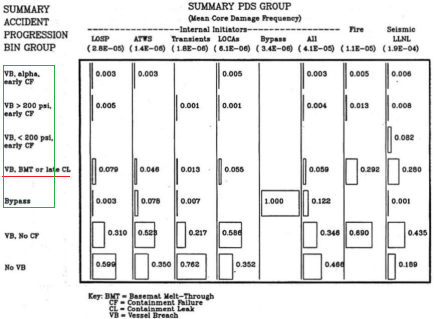

P_SBO = 2.83e-5;        % probab' of different events
P_ATWS = 1.4e-6;
P_Tr = 1.8e-6;
P_LOCA = 6.1e-6;
P_Bp = 3.4e-6;

P_D = [P_SBO, P_ATWS, P_Tr, P_LOCA, P_Bp]   % Damage probab' vector

P_D = 1.0e-04 *

    0.2830    0.0140    0.0180    0.0610    0.0340


Now, also from the figure, we get-

P_AD11 = 0.003 + 0.005 + 0.003;     % LOSP; alf +200 psi +bypass 
P_AD12 = 0.003 + 0 + 0.078;         % ATWS
P_AD13 = 0 + 0.001 + 0.007;         % Tr
P_AD14 = 0.005 + 0.004 + 0;         % LOCA
P_AD15 = 0 + 0 + 1;                 % Bypass

P_AD1 = [P_AD11, P_AD12, P_AD13, P_AD14, P_AD15]; % early CF (accidents)

P_AD2 = [0.079, 0.046, 0.013, 0.055, 0]; % late CF

P_AD = [P_AD1; P_AD2]               % probab' of CF, given damages

P_AD =     0.0110    0.0810    0.0080    0.0090    1.0000
    0.0790    0.0460    0.0130    0.0550         0


From RSANS, we know that-

P_A = P_AD * P_D'               % probab of CF(rad' release); 1/reactor y

P_A = 1.0e-05 *

    0.3894
    0.2659


P_A = [early CF, late CF]

############### ###############

## Prob-8.3.2a

From the RSANS book eq-10.26, we have-


$$\frac{Q_i \left(T\right)}{Q_i \left(0\right)}=\frac{M_i \left(T\right)}{M_i \left(0\right)}$$


Then, we have, from Appendix Table A1, The radioactive inventory

Q_01 = 0.6 + 26 + 51 + 73 + 183 + 37;        % MCi
Q_02 = 91 + 129 + 183 + 204 + 161;
Q_03 = 0.028 + 8.1 + 3.2 + 5.1;
Q_04 = 6.3 + 1.2 + 33 + 5.7 + 14 + 129 + 6.6 + 35;
Q_05 = 101 + 4 + 118;
Q_06 = 172 + 151 + 118 + 77 + 27 + 53;
Q_07 = 4.2 + 129 + 161 + 161 + 172 + 140 + 65;
Q_08 = 161 + 140 + 91 +  1800 + 0.061 + 0.023 + 0.023 + 3.7;
Q_09 = 172;

Then, the equilibrium radioactivity inventory would be-

Q_0 = [Q_01, Q_02, Q_03, Q_04, Q_05, Q_06, Q_07, Q_08, Q_09]    % initial activity; MCi

Q_0 = 1.0e+03 *

    0.3706    0.7680    0.0164    0.2308    0.2230    0.5980    0.8322    2.1958    0.1720


### Prob-8.3.2b

From table 10.4, we have the follows-

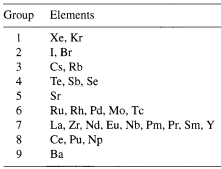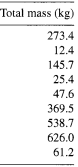

M_0 = [273.4, 12.4, 145.7, 25.4, 47.6, 369.5, 538.7, 626, 61.2];   % initial mass; kg 

Table 10.5, we have mass at T=24 hours into the accident-

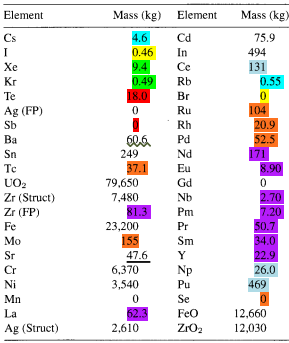

M_T1 = 9.4 + 0.49;          % kg
M_T2 = 0.46;
M_T3 = 0.55 + 4.6;
M_T4 = 18 + 0 +0;
M_T5 = 47.6;
M_T6 = 104 +20.9 +155 +37.1;
M_T7 = 62.3 +81.3 +171 + 2.7+ 7.2 + 34 +22.9;
M_T8 = 131 + 469 + 26;
M_T9 = 60.6;

M_T = [M_T1, M_T2, M_T3, M_T4, M_T5, M_T6, M_T7, M_T8, M_T9]     % mass at accident; kg

M_T =     9.8900    0.4600    5.1500   18.0000   47.6000  317.0000  381.4000  626.0000   60.6000


Then, using equation 10.26, we get-

Q_T = M_T./M_0 .*Q_0                % radioactivity at accident; MCi

Q_T = 1.0e+03 *

    0.0134    0.0285    0.0006    0.1636    0.2230    0.5130    0.5892    2.1958    0.1703


############### ###############

## Prob-8.3.3

From figure 10.10

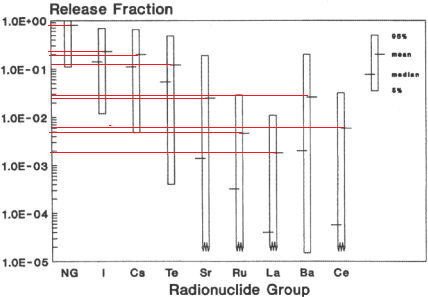

Probability density functions for release fraction *f(Si\ Aj *) in nine radionuclide groups for early containment failure due to Surry containment bypass events.

We have probability of release fraction S, given A1

% Grp = [NG,  I,    Cs,  Te,   Sr,    Ru,    La,    Ce,    Ba ]
f_SA1 = [0.7, 0.25, 0.2, 0.15, 0.025, 0.005, 0.002, 0.006, 0.03];   % release fraction

Similarly

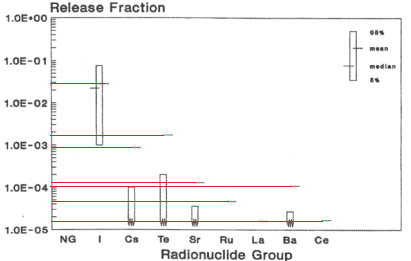

Probability density functions for release fraction *f(Si\Aj *) in nine radionuclide groups for Surry late-containment failure events

% Grp = [NG,  I,    Cs,     Te,     Sr,     Ru,    La,     Ce,     Ba ]
f_SA2 = [0,   3e-2, 9e-4,  1.8e-4, 1.1e-4, 4.5e-5, 0.5e-5, 0.5e-5, 1e-4];  % release fraction

Now, let's use the equation 10.15 from the book

  to find f(Si|Ai)

Q_T;                        % Radionuclide release, previous; MCi
P_SA1 = Q_T .*f_SA1         % amount of release from A1, ECF; MCi

P_SA1 =     9.3843    7.1226    0.1161   24.5339    5.5750    2.5652    1.1784   13.1748    5.1094


P_SA2 = Q_T .*f_SA2         % ...of A2, LCF; MCi

P_SA2 =          0    0.8547    0.0005    0.0294    0.0245    0.0231    0.0029    0.0110    0.0170


Then, combining the two-

P_A;                        % ECF & LCF probab', previously
P_SA = [P_SA1; P_SA2];      % forming matrix, amount of release; MCi
P_S = P_SA' * P_A *1e6      % radioactive release; Ci/yr

P_S =    36.5424
   30.0080
    0.4536
   95.6131
   21.7743
   10.0502
    4.5965
   51.3320
   19.9413


So, total radioactive release should be-

P_S_T = sum(P_S)            % total rad' release; Ci/yr

P_S_T = 270.3115

(Ans)

############### ###############

## Prob-8.3.4

Let's use the Gaussian plume model

Let's what we found in Problem 7.4 for x = 5 km

F_y = 0.0722;           % coefficeint          
F_ye = 0.9031;          % exponent
x = 5e3;                % distance; m
sg_y = F_y*x^F_ye       % dispersion coeff.; m

sg_y = 158.1528

Then, 

F_z = 0.2;              % coefficeint          
F_ze = 0.602;           % exponent
sg_z = F_z*x^F_ze

sg_z = 33.7140

So, for dispersion factor


$$\frac{\chi }{Q}=\frac{1}{\pi \;\sigma_y \sigma_z \;u\;}$$
  
$$\left\lbrack \frac{s}{m^3 }\right\rbrack$$
 

u = 1;              % wind speed; m/s
% Q                 % radioactivity; Ci/s
% Chi               % Ci/m^3
  dnm = pi*sg_y*sg_z *u;
Ch_Q = 1/dnm        % s/m^3

Ch_Q = 5.9698e-05

So, we have, for dose-


$$D=0\ldotp 507\;E_{\gamma \;} \frac{\chi }{Q}q\;$$


E_g = 1;        % gamma energy; MeV
q = P_S_T;      % ; Ci/yr

D = 0.507 *E_g*Ch_Q *q;     % dose rate; rem/yr
D = D *1e3                  % mRem/y

D = 8.1816

############### ###############

## Prob-8.3.5a

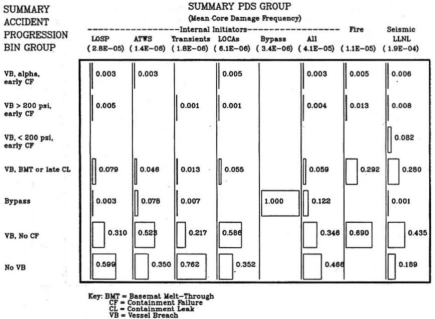

for SBO

P_D1 = P_SBO             % probab' of damage- SBO/LOSP

P_D1 = 2.8300e-05

P_AD_SB = P_AD(:,1)      % probab' of CF(ECF, LCF), from SBO

P_AD_SB =     0.0110
    0.0790


P_A_SB = P_AD_SB *P_D1   % CF from SBO; CF; 1/yr

P_A_SB = 1.0e-05 *

    0.0311
    0.2236


Likewise, for Containment Bypass

P_D5 = P_Bp             % probab' of damage- Bypass

P_D5 = 3.4000e-06

P_AD_Bp = P_AD(:,5)     % probab' of CF(ECF, LCF), from BP

P_AD_Bp =      1
     0


P_A_Bp = P_AD_Bp *P_D5  % CF from Bypass; 1/yr

P_A_Bp = 1.0e-05 *

    0.3400
         0


Now, given-

f_r = 2e-4;         % fatality /person-rem; #/rem
f = f_r*D*1e-3      % fatalities; #/yr

f = 1.6363e-06

Let's find out- contribution of particular damage state

**for SBO**

P_SA;                       % amount of release, given CF happened; MCi
P_A_SB;                     % amount of release from SBO; MCi
P_S_SB = P_SA' *P_A_SB *1e6;    % rad' release; SBO Ci
P_S_SBT = sum(P_S_SB)       % total release, from SBO; Ci

P_S_SBT = 23.5584

Now, for relative contribution

P_S_T                       % total rad' release; Ci/yr

P_S_T = 270.3115

r_SB = P_S_SBT/P_S_T*100    % relative contribute, SBO; %

r_SB = 8.7153

For dose and fatality,

D_SB = 0.507 *E_g*Ch_Q*P_S_SBT  % rem/yr

D_SB = 7.1305e-04

f_SB = D_SB *f_r                % early fatality for release from SBO; #/yr

f_SB = 1.4261e-07

f_nrg = 1e-6;                   % early fatality per NUREG-1150; #/yr
r_f = f_SB/f_nrg *100           % fatality ratio; %

r_f = 14.2609

**for Bypass**

P_S_Bp = P_SA' *P_A_Bp *1e6;    % rad' release; SBO Ci
P_S_BpT = sum(P_S_Bp)           % total release, from SBO; Ci

P_S_BpT = 233.7829


r_Bp = P_S_BpT/P_S_T *100       % relative contribute, bypass; %

r_Bp = 86.4865

Now for dosage and fatality

D_Bp = 0.507 *E_g*Ch_Q*P_S_BpT  % rem/yr

D_Bp = 0.0071

f_Bp = D_Bp *f_r                % early fatality for release from Bp; #/yr

f_Bp = 1.4152e-06

f_nrg2 = 1.6e-6;                % early fatality per NUREG-1150; #/yr
r_f2 = f_Bp/f_nrg2 *100          % fatality ratio; %

r_f2 = 88.4492

(Ans)

from the RSANS fig 10.15, we see-

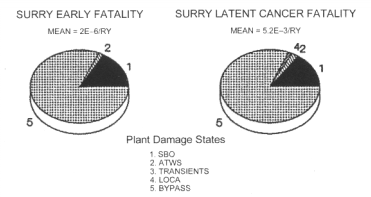 (Partial)

that, the SBO and Bypass event are two major contributors of early fatalities (and later, cancer)

############### ###############

## Prob-8.3.5b

Here, for factor of 20 reduction for late release

Q_02 = Q_0/20                % reduced inventory; MCi

Q_02 =    18.5300   38.4000    0.8214   11.5400   11.1500   29.9000   41.6100  109.7904    8.6000


Therefrom,

Q_T2 = M_T./M_0 .*Q_02;        % radioactivity at accident; MCi

So, here,

P_SA22 = Q_T2 .*f_SA2         % amount of release from A2, LCF; MCi

P_SA22 =          0    0.0427    0.0000    0.0015    0.0012    0.0012    0.0001    0.0005    0.0009


Then, release matrix would be-

P_SA2 = [P_SA1; P_SA22];      % forming matrix, amount of release; MCi
P_S2 = P_SA2' * P_A *1e6      % radioactive release; Ci/yr

P_S2 =    36.5424
   27.8490
    0.4523
   95.5388
   21.7123
    9.9918
    4.5891
   51.3043
   19.8983


And then-

P_S_T2 = sum(P_S2)            % total rad' release with reduced inventory; Ci/yr

P_S_T2 = 267.8783

Previoulsy we got

P_S_T                       % total rad' release

P_S_T = 270.3115

We see, despite reducing the inventory with a factor of 20, the release-rate doesn't dwindle that much. 

############### ############### ############### ############### 

## Prob-8.4

Let's do the following assumptions

C_PD = 10e9;    % permanent damage to plant; $

**Evacuation Cost**

C_ev_r = 200;   % cost /day/person for evacuation; $
 p = 5e3;       % no. of persons; usual
 d = 3;         % no. of days necessary for evacuation
C_ev = C_ev_r *p*d  % total cost in evacuation; $

C_ev = 3000000

**Cost related to death-toll**

C_lf = 10e6;    % life's value; $
d = 100;        % dose to nearby populace; Sv
rt = 0.05;      % mortality rate /sv, assumed
C_lfT = C_lf *d*rt  % total life cost; $

C_lfT = 50000000

**Total cost** from a single accident

C_T = C_PD + C_ev + C_lfT         % ; $

C_T = 1.0053e+10

Now, let's evalute the cost- if accident happens

f = 1e-7;           % accident frequency
C_Ty = f *C_T       % cost entailed per yera; $/y

C_Ty = 1.0053e+03

**Installing New Heat Removal System**

C_cp = 10e6;           % capital investment; $
C_ma = 0.1e6;           % annual maintenance; $
t = 40;                 % reactor's lifetime; y
r = 0.05;               % discount rate

Now, let's use the following equation to find equivalent annual cost


$$C_{\textrm{eq}} =\frac{r\;C_{\textrm{cp}} }{1-{\left(1+r\right)}^{-t} }+C_{\textrm{an}}$$


C_eq = r* C_cp/(1- (1+r)^-t) + C_ma  % $/y

C_eq = 6.8278e+05

Now, by incorporating coolant system, if the frequency could be truncated down to factor of 10

f2 = f/10;           % renewed freq'
C_Ty2 = f2*C_T       % ; $/y

C_Ty2 = 100.5300

 Then, the total cost should be

C_Ty2 = C_Ty2 + C_eq 

C_Ty2 = 6.8288e+05

So, we can find that the annual cost after installing a HRS becomes 6.82E5 $, which far exceeds the cost withour HRS of 1.0053E3 $. So, the investment is **not justifiable**.